# Q4

clear
load('Assignment_Data_SC42145.mat');
load('Q2_syn.mat'); 
K = minreal(K);

22 states removed.


G = tf(FWT(1:2,1:2));


## Build Matrices

wb = 0.8*pi;
% Wp11 = tf([1/1.8, wb*1e4], [1, wb*1e4*1e-4]);
% %Wp11 = tf([0.5556, 2.0897],[1 2.0897e-4]);
% figure()
% bodemag(Wp11, {1e-4; 1e6}); hold on;
% 
Wp11 = tf([1/1.8, wb], [1, wb*1e-4])

Wp11 =
 
  0.5556 s + 2.513
  ----------------
   s + 0.0002513
 
Continuous-time transfer function.



% bodemag(Wp11, {1e-4; 1e6}); 
% xline(0.8*pi);
% legend("New design", "Original design", "0.8pi")

Wu22 = tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6]);

Wp = [Wp11 0; 0 0.2];
Wu = [0.01 0; 0 Wu22];

% build Uncertainty Weight matrices
Wi1 = tf([1/(16*pi), 0.3], [1/(64*pi), 1]);
Wi2 = Wi1;
Wo1 = tf([0.05, 0.2], [0.01, 1]);
Wo2 = Wo1;

Wi = blkdiag(Wi1, Wi2);
Wo = blkdiag(Wo1, Wo2);

% Build Delta Block
D1 = ultidyn('Din1', [1,1], 'Bound', 1);
D2 = ultidyn('Din2', [1,1], 'Bound', 1); 
D3 = ultidyn('Dout1', [1,1], 'Bound', 1); 
D4 = ultidyn('Dout2', [1,1], 'Bound', 1);
Din = blkdiag(D1, D2);
Dout = blkdiag(D3, D4);
D = blkdiag(Din, Dout);

evalfr(Wi1, 1e-5)

ans = 0.3000

evalfr(Wi1, 47)

ans = 1.0010

evalfr(Wi1, 1e5)

ans = 3.9926

evalfr(Wo1, 1e-5)

ans = 0.2000

evalfr(Wo1, 20)

ans = 1

evalfr(Wo1, 1e5)

ans = 4.9952

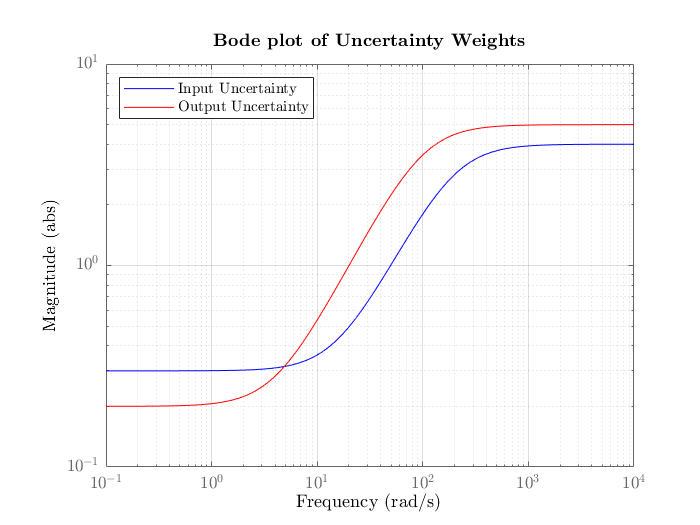

% plot weights
figure();
bodemag(Wi1, 'blue'); hold on;
latex_bodemag(Wo1, 'Uncertainty Weights', 'red');
legend('Input Uncertainty', 'Output Uncertainty', 'interpreter', 'latex', 'Location', 'northwest');
yticks([0.1, 1, 10]); ylim([0.1; 10])
saveas(gcf, 'Figures/ch4_uncertainty_weights.eps',  'epsc');


% plot uncertain system, see Q5
figure();
% sigma(ultidyn('d',[2,2],'Bound',1)*G);
% saveas(gcf, 'Figures/ch4_uncertain_dynamics.eps', 'epsc');

## Generalized Plant

P11 = [zeros(2,4); 
       Wo*G zeros(2,2)];
P12 = [zeros(2,2) Wi; 
       zeros(2,2) Wo*G];
P21 = [Wp*G Wp; 
       zeros(2, 4)];
P22 = [Wp Wp*G; 
       zeros(2,2) Wu];
P31 = [-G -1*eye(2)];
P32 = [-1*eye(2) -G];

%P21 = [Wp*G Wp; 
%       Wu, zeros(2, 2)]; %if Wu after uncertainty


P = [P11 P12; 
     P21 P22; 
     P31 P32];
P.OutputName = {'y_1d1'; 'y_1d2'; 'y_2d1';'y_2d2';'z_11'; 'z_12';'z_21'; 'z_22';'v_1';'v_2'};
P.InputName = {'u_1d1'; 'u_1d2'; 'u_2d1'; 'u_2d2'; 'w_1'; 'w_2'; 'u_1'; 'u_2'};

save("P_q4.mat", "P", "Wi", "Wo", "Wp", "Wu")

K.InputName = {'v_1';'v_2'};
K.OutputName = {'u_1'; 'u_2'};


%N = lft(P,K);
N_inputnames = {'u_1d1'; 'u_1d2'; 'u_2d1'; 'u_2d2'; 'w_1'; 'w_2';};
N_outputnames = {'y_1d1'; 'y_1d2'; 'y_2d1';'y_2d2';'z_11'; 'z_12';'z_21'; 'z_22'};

tf_y_v = -1;
N = connect(P,tf_y_v*K, N_inputnames, N_outputnames);


## Assessment

L = (eye(2)-P(9:10,7:8)*K);
latex_nyquist(L(2,2)*L(1,1)-L(2,1)*L(1,2), 'Generalized Nyquist')

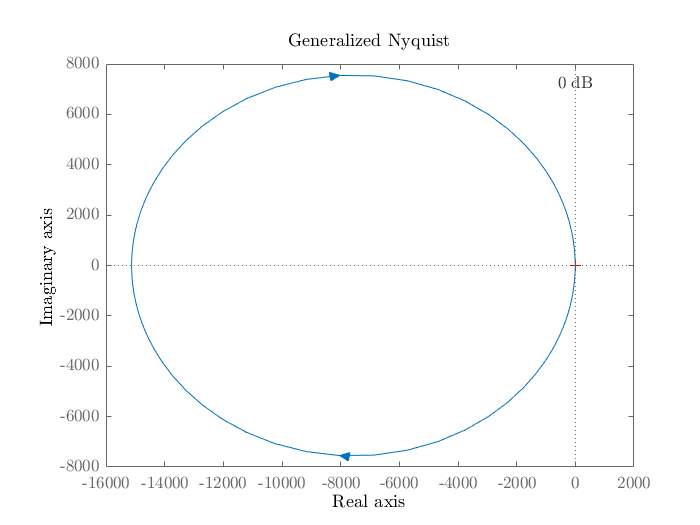

saveas(gcf, 'Figures/ch4_nyquist.eps','epsc');

all(real(pole(L))<0)

ans = logical
   0


evalN(N)

all tf's are individually stable --> NS
Nominal stability: true (-0.000251) 
Points completed: 150/150
Nominal performance: true (0.797331) 
Points completed: 150/150
Robust stability: true (0.799696) 
Points completed: 150/150
Robust performance: false (1.741834) 


SSV analysis of Question 2.5 --> see part2_connect.mlx